% *************************************************************
% GMCM2019D Code
%   Driving cycle
% 
% Date: 2019/09/19
% Copyright: 
% *************************************************************

clear


%% read files and extract date
header = {'time','velocity','accelx','accely','accelz','longitude', ...
    'latitude','engine_revolution','torque_percentage','consumption', ...
    'pedal_opening','air_fuel_ratio','load','air_flow'};
filename = '';
max_try = 3;
while isempty(filename) && max_try > 0
    [file, path] = uigetfile('*.xlsx');
    if file ~= 0
        filename = [path, file];
        break
    end
    disp('Please select a data file!')
    max_try = max_try - 1;
end
rawdata = readtable(filename);

rawdata.Properties.VariableNames = header;
rawdata.time = datetime(rawdata.time, "InputFormat", "yyyy/MM/dd HH:mm:ss.SSS.");

%% GPS Signal lost location
latitude_lost = rawdata.latitude == 0;
longitude_lost = rawdata.longitude == 0;
% make sure they match
if ~all(latitude_lost == longitude_lost)
    disp("GPS signal lost data doesn't match!!!")
end

%% data cleaning and statistics
% split raw data into pieces
idx = extract_slice(rawdata.velocity);
tic;
% preprocess and statistics
min_revolution = 600;
interval = [10 20 40 80 140];
thresh = seconds(60);
len = length(idx);
z = zeros(len, 1);
d = struct('raw', z, 'raw_stats', z, 'processed', ...
    z, 'stall', z, 'processed_stats', z, 'groupid', z);
for i = 1:len-1
    d(i).id = i;
    d(i).raw = rawdata(idx(i):idx(i+1)-1, :);
    d(i).raw_stats = statistics(d(i).raw);
    [d(i).processed, d(i).stall] = preprocess(d(i).raw, min_revolution, thresh);
    d(i).processed_stats = statistics(d(i).processed);
    d(i).groupid = segregate2group(d(i).processed_stats, interval);
end
toc;

时间已过 14.234490 秒。


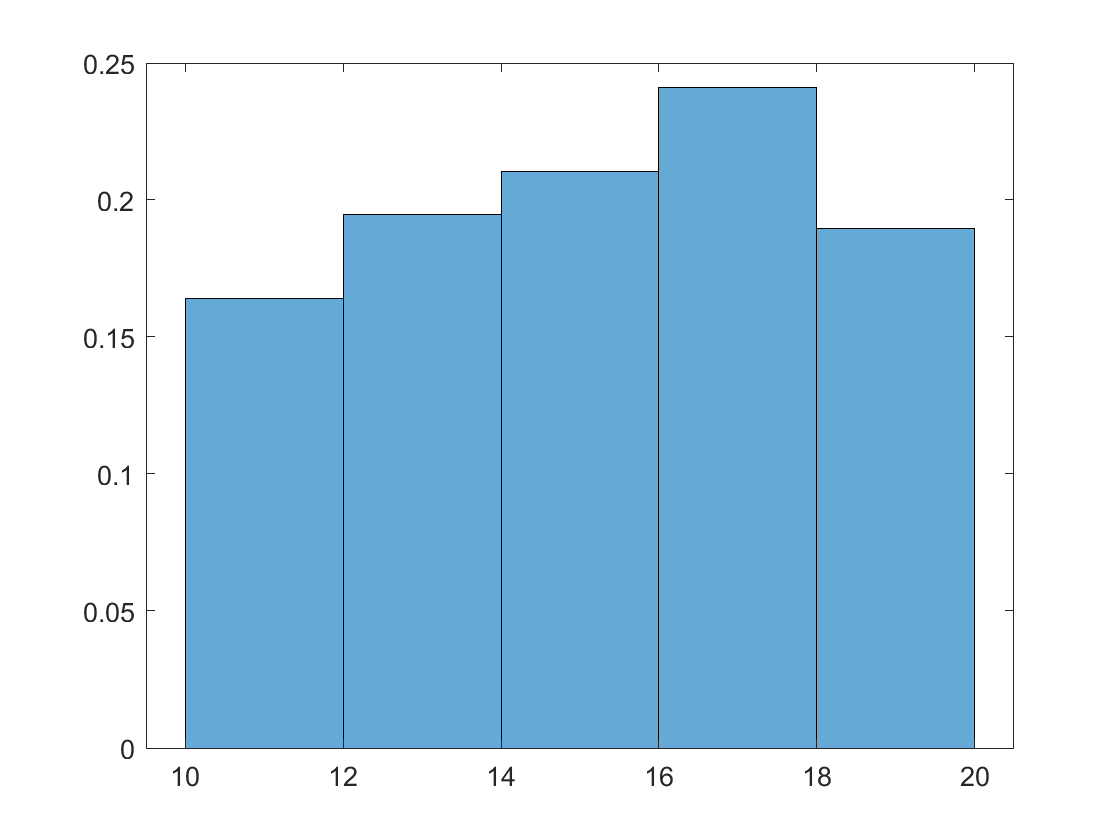

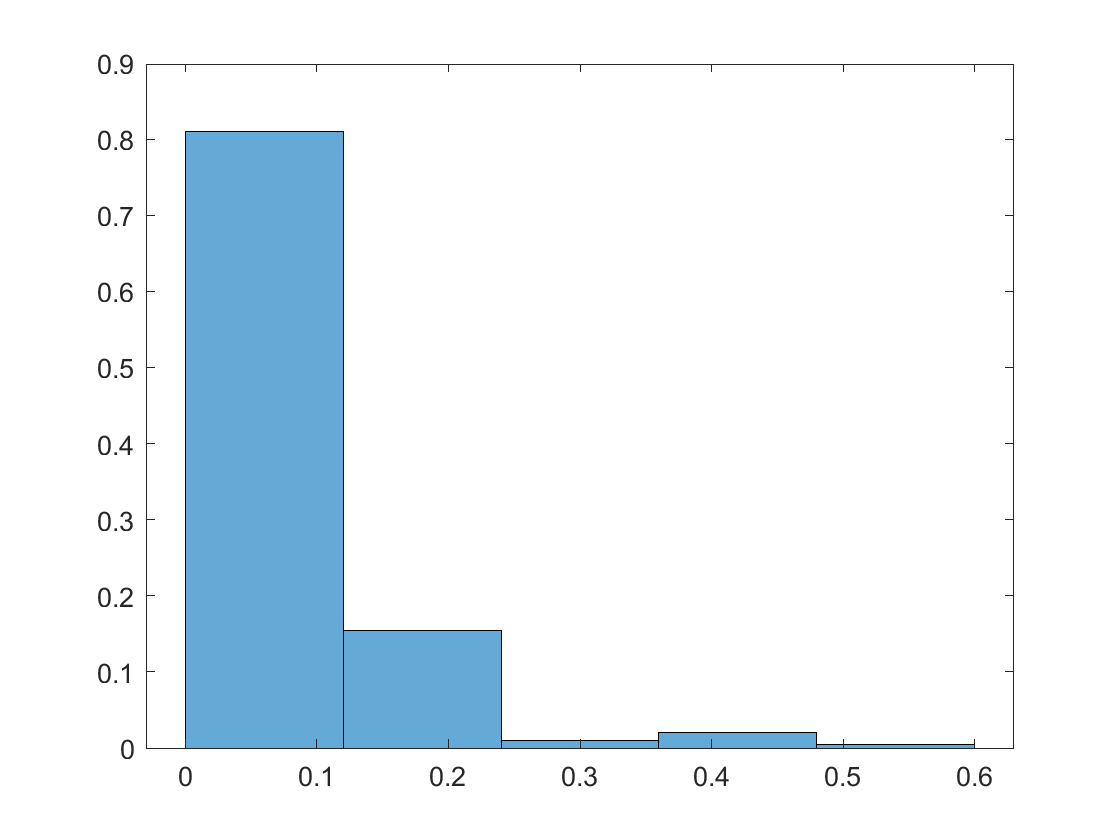

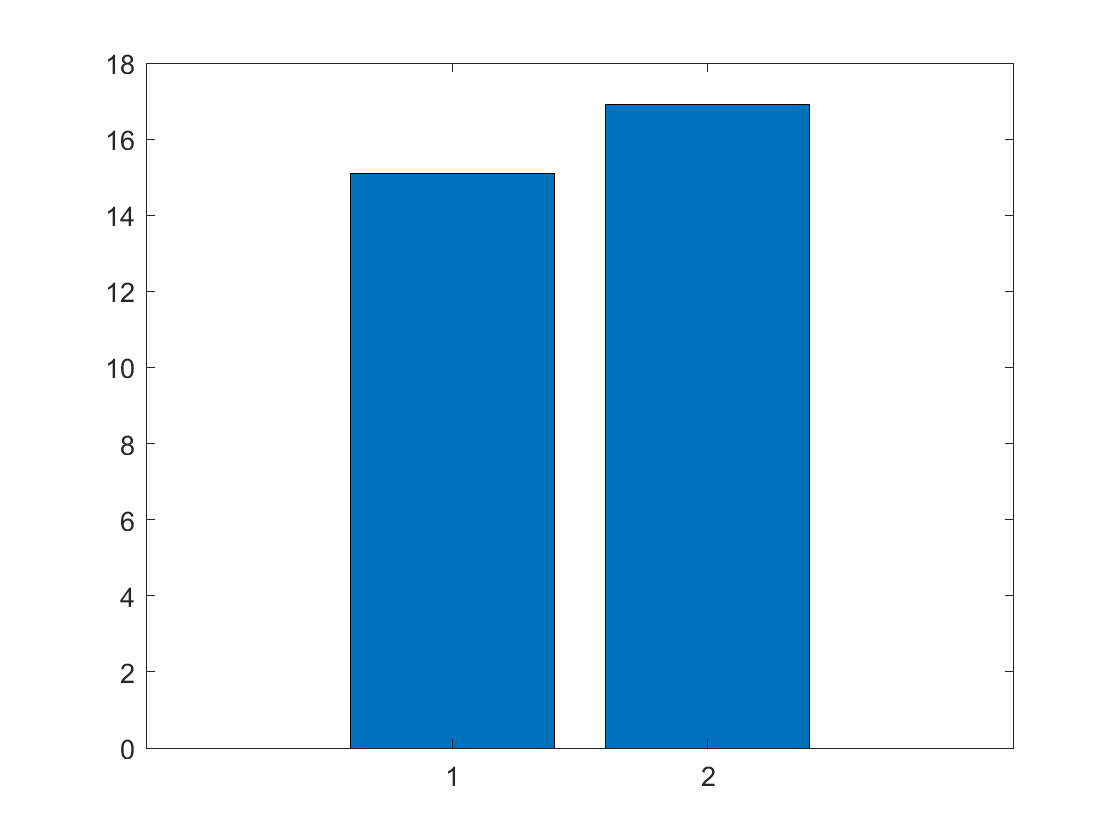

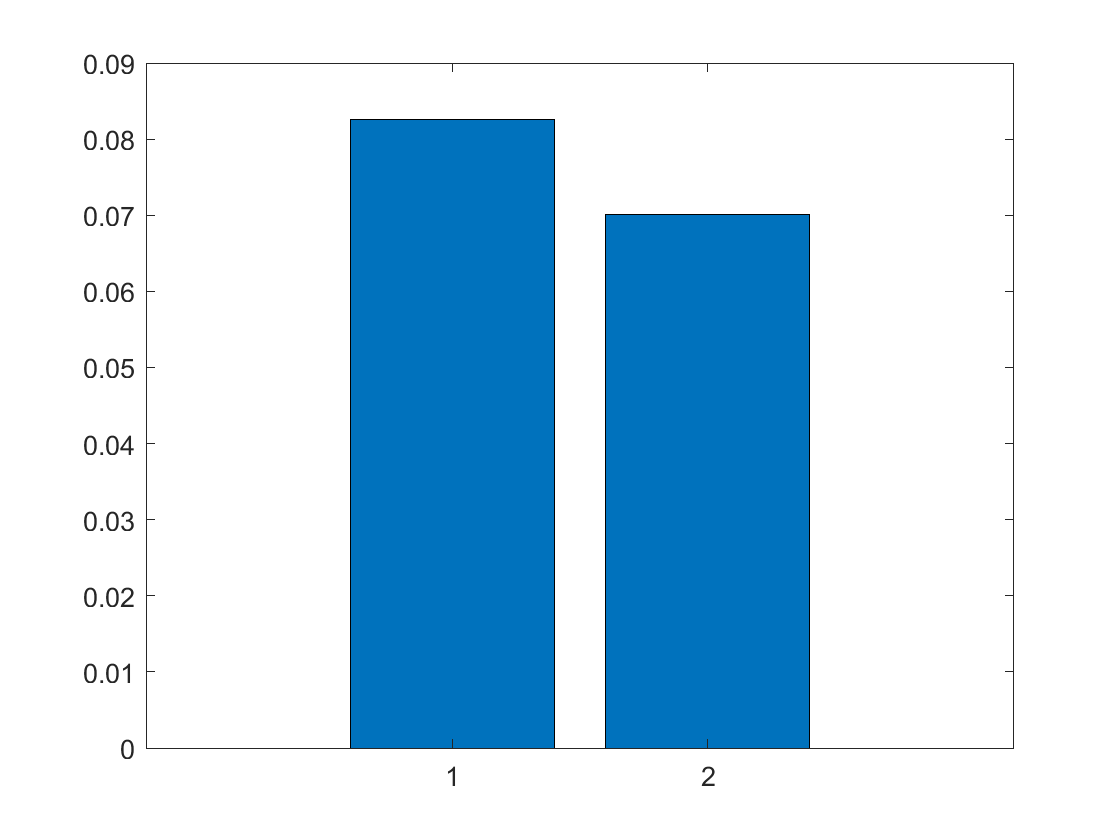

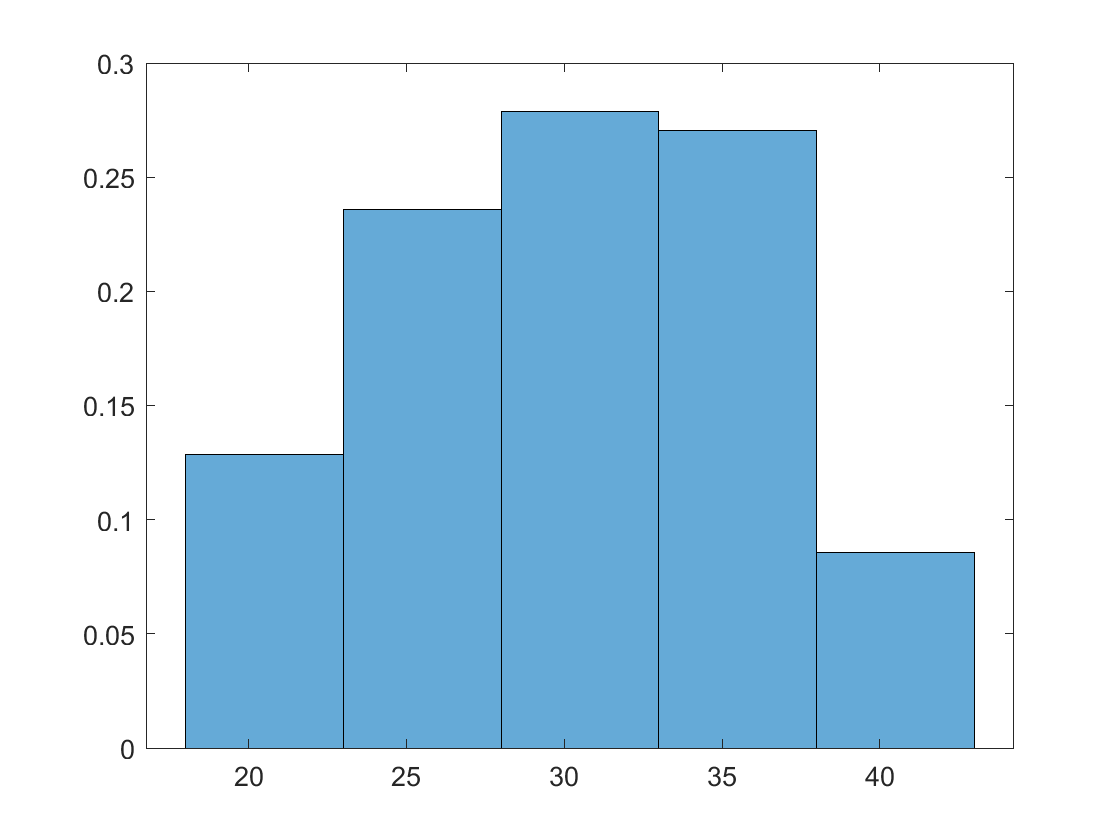

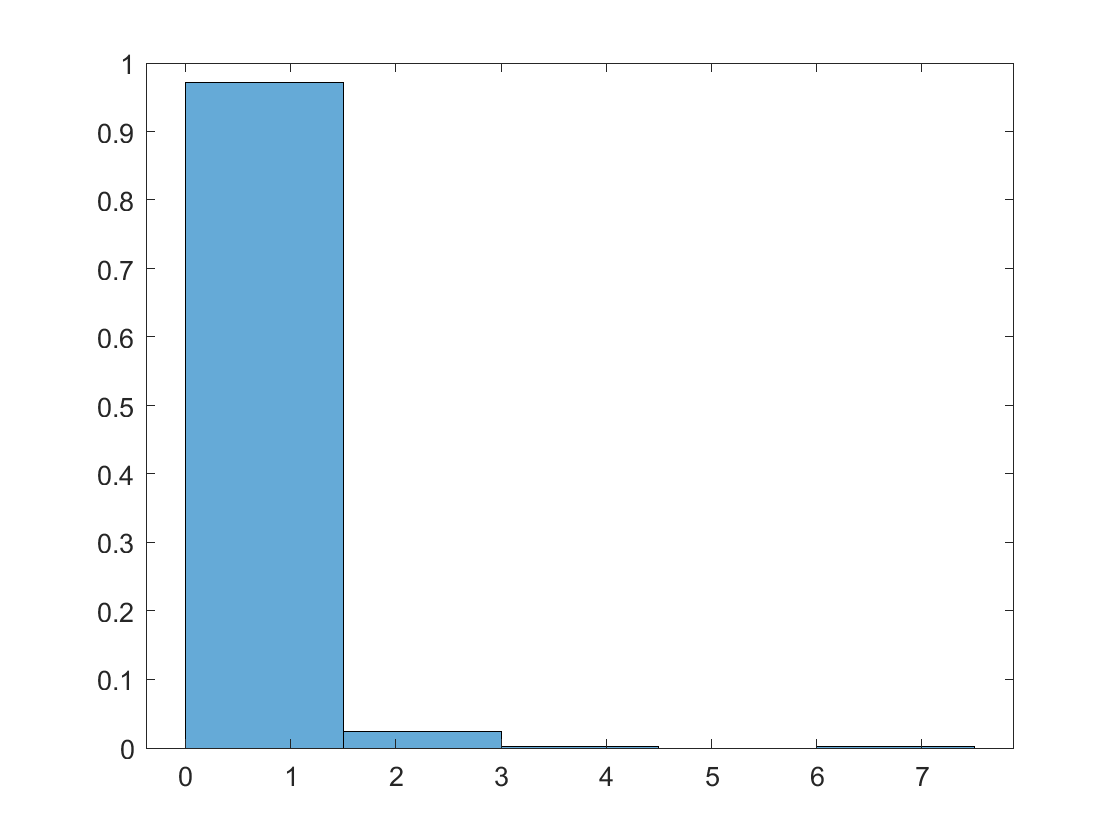

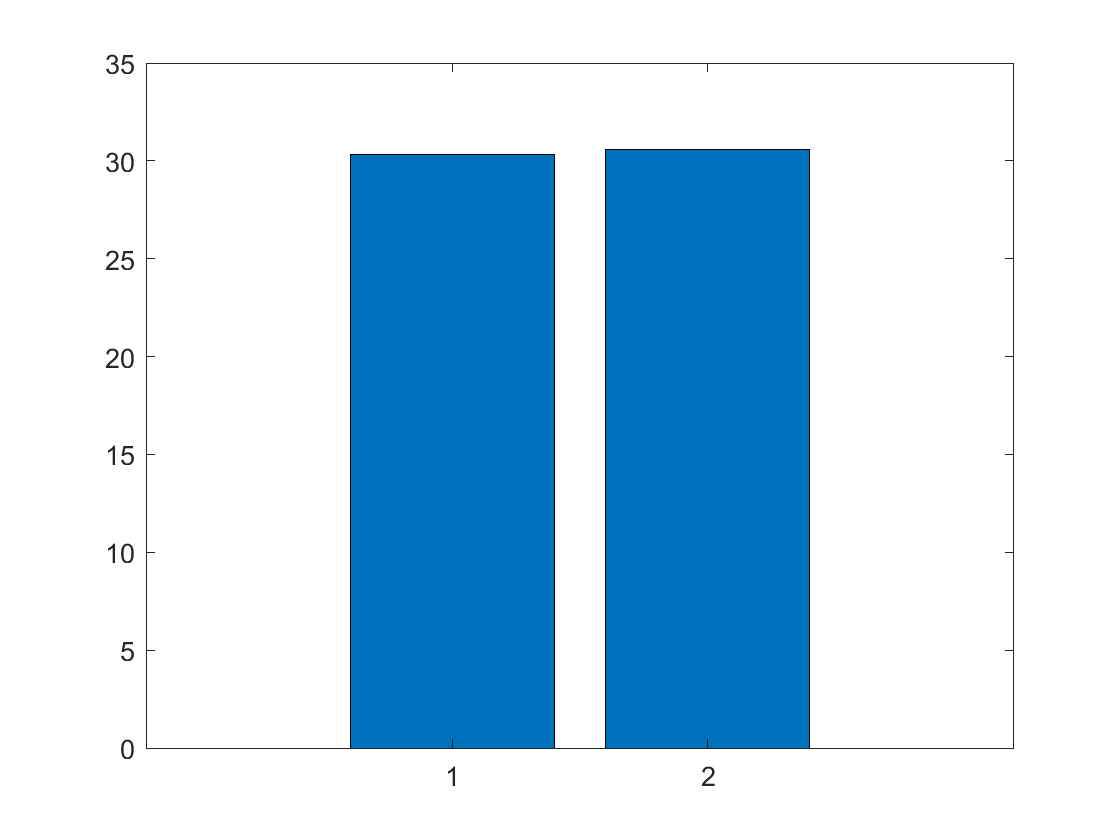

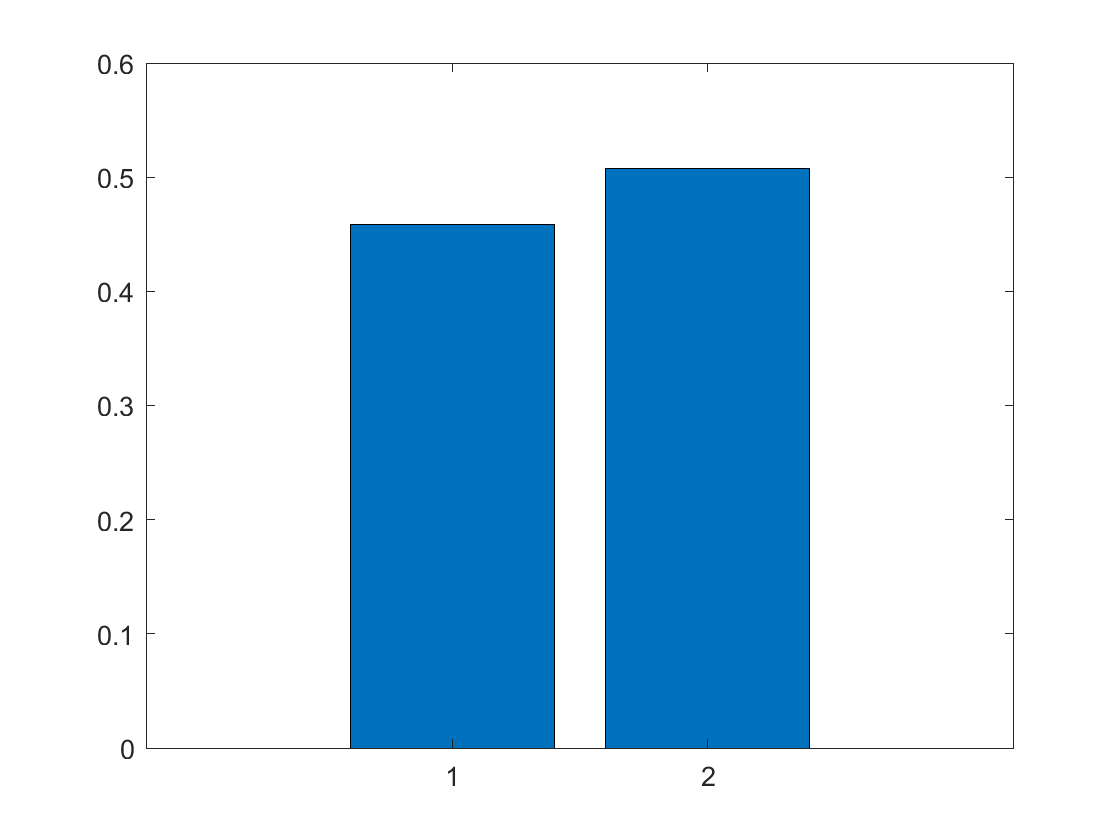

%% construction of driving cycle
Trep = 1300;
Tfull = sum(extract_distance(d));
Tdrive = sum(extract_total_drive_time(d));
len_interval = length(interval) - 1;
bincounts = 5;

% dived into groups
% group = cell(len_interval, 1);

% for each group
% select the most representative slices in the group
selected_group = [];
for i = 1:4
    group = match_group(d, i);
    selected_group = cat(2, selected_group, select(group, Tfull, Trep, bincounts)); 
end


% find corresponding location in the representative cycle
% calculate idle time
% insert idle time
% adjust overall time

% statistics
% graphs
% etc...



%% Geo Map
webmap('Open Street Map')
s = geoshape(rawdata.latitude(~latitude_lost), rawdata.longitude(~longitude_lost));
wmline(s,'Color', 'b', 'Width', 1);